# **Páncreas Artificial: PID comercial.**

**Elaborado por: **Manuela María Muriel Tobar, David Andrés Ojeda Guzmán

**Universidad de Nariño**

Se implementa y analiza un controlador PID diseñado para emular el comportamiento típico de una bomba comercial. El sistema actúa sobre el modificado de Bergman.

Además del diseño del PID, se incorpora un escenario de simulación de 24 horas con resolución de 1 minuto, 3 ingestas de comida (desayuno, almuerzo, cena), una referencia variable que trata de imitar el ritmo circadiano de la persona.

Se evaluan tanto metricas clinicas como de control

close all; clear variables; clc;

p1 = 0.03; % Tasa de eliminación de glucosa independiente de insulina
p2 = 0.02; % Tasa de desaparición de la acción de la insulina
p3 = 4.5e-5; % Sensibilidad a la insulina
p4 = 0.08; % Tasa de degradación de la insulina
Gb = 90; % Glucosa basal (mg/dl)
Ib = 10; % Insulina basal (mU/dl)
VI = 12; % Volumen de distribución de insulina (dl)

** Diseño del controlador PID para regulación de glucosa**

El controlador PID tiene como objetivo mantener la glucosa en sangre dentro del rango saludable (70–180 mg/dL), compensando las variaciones que generan las comidas y las respuestas individuales del paciente.

La estrategia combina:

- Un control PID,

- bolos preprogramados en los horarios de comida.

G_ref_initial = 100; % Asumimos 100 mg/dl como referencia inicial 
X_ref = (p1*(Gb - G_ref_initial))/G_ref_initial;
I_ref = Ib + (p2*X_ref)/p3;

**Cálculo del estado basal (equilibrio sin perturbaciones)**

Se considera un nivel deseado de glucosa sin perturbaciones (ej: 100 mg/dL) y se calcula la insulina basal necesaria para mantenerlo estable.

 Esto se hace calculando:

-  La acción de insulina activa $X_{ref}$

-  La insulina en sangre $I_{ref}$

-  la tasa de infusión basal $U_{ref}$

 Estas condiciones definen el equilibrio del sistema sin comidas.

U_ref = p4*VI*I_ref; 

% 3. Parámetros PID 
Kp = 0.08;   % Ganancia proporcional
Ki = 0.002;  % Ganancia integral
Kd = 0.02;   % Ganancia derivativa
N = 10;      % Filtro derivativo

meal_times = [7*60, 13*60, 20*60]; % 7:00, 13:00, 20:00
meal_durations = [30, 45, 30]; 
meal_amounts = [12, 20, 15]; 

bolus_amounts = [4.5, 7.0, 5.5]; % mU de insulina por bolo 
bolus_durations = [10, 15, 10]; % Duración del bolo extendida
bolus_advance_time = [20, 25, 20]; % Mayor tiempo de anticipación

D = @(t) meal_amounts(1)*smooth_meal_profile(t, meal_times(1), meal_durations(1)) + ...
         meal_amounts(2)*smooth_meal_profile(t, meal_times(2), meal_durations(2)) + ...
         meal_amounts(3)*smooth_meal_profile(t, meal_times(3), meal_durations(3));

% Función de bolos programados
U_bolus = @(t) bolus_amounts(1)*smooth_bolus_profile(t, meal_times(1)-bolus_advance_time(1), bolus_durations(1)) + ...
               bolus_amounts(2)*smooth_bolus_profile(t, meal_times(2)-bolus_advance_time(2), bolus_durations(2)) + ...
               bolus_amounts(3)*smooth_bolus_profile(t, meal_times(3)-bolus_advance_time(3), bolus_durations(3));

%% 5. Simulación del sistema
tspan = 0:1:24*60; % 24 horas en minutos
% Condiciones iniciales [G; X; I; Dt; Gsc]
y0 = [G_ref_initial; X_ref; I_ref; 0; G_ref_initial]; 

G = zeros(size(tspan));
I_plasma = zeros(size(tspan)); 
U_total = zeros(size(tspan));
U_PID = zeros(size(tspan));
U_bolus_vals = zeros(size(tspan));
Error = zeros(size(tspan));
G_ref_vals = zeros(size(tspan));

e_prev = 0;
integral = 0;
max_integral = 30; 
derivative_filtered = 0; 
y = y0;

 El controlador se basa en el error entre la glucosa deseada (referencia) y la medida en tiempo real.

####  Mecanismos de seguridad en el control

 Para que un sistema de control automático de glucosa sea viable en un contexto clínico, debe evitar:

- Aplicar insulina innecesaria ante fluctuaciones menores.

- Acumular errores antiguos que ya no son relevantes.

- Administrar dosis excesivas que puedan provocar hipoglucemia.

En este controlador PID, se implementaron varios mecanismos de seguridad y robustez siguiendo las indicaciones anteriores. A continuación se detallan:

-  **Zona muerta:** Si el error entre la glucosa medida y la referencia(±3 mg/dL), el controlador no actúa. Esto evita oscilacionesinnecesarias y sobrecontrol.

-  **Anti-windup**: la integral del error se limita para evitar sobrecorrección.

- **Decaimiento de la integral: **se reduce su peso si no hay error persistente.

- **Derivada filtrada: **la derivada puede ser muy sensible al ruido o pequeñas variaciones, por lo que se filtra mediante un promedio exponencial.

- **Límites adaptativos:** Para evitar sobredosis de insulina, la acción total del PID se restringe dentro de rangos seguros: Si hay bolo activo (comida reciente): ±3 mU/min,  Si no hay bolo: ±6 mU/min.

for i = 1:length(tspan)
    t = tspan(i);
    
    % Obtener el valor de referencia de glucosa actual
    G_ref_current = smooth_glucose_reference(t); 
    G_ref_vals(i) = G_ref_current; % Almacenar para graficar o analizar
    
    % Calcular bolo programado
    U_bolus_vals(i) = U_bolus(t);
    
    % Calcular error usando la referencia dinámica
    error = G_ref_current - y(1); 
    Error(i) = error;
    
    dead_zone = 3;
    if abs(error) > dead_zone
        % Términos PID
        P = Kp * error;
        
        % Integral con anti-windup y decaimiento
        if abs(error) < 15 % Solo integrar para errores moderados
            integral = integral + error;
        end
        integral = integral * 0.995; % Decaimiento lento
        integral = max(min(integral, max_integral), -max_integral);
        I_term = Ki * integral; 
        
        % Derivativo
        if i > 1
            derivative_raw = error - e_prev;
            derivative_filtered = derivative_filtered + (derivative_raw - derivative_filtered) / N;
            D_term = Kd * derivative_filtered;
        else
            D_term = 0;
        end
        
        % Acción de control PID
        u_pid = P + I_term + D_term;
    else
        % Dentro de zona muerta, no actuar con PID
        u_pid = 0;
        integral = integral * 0.98; % Reducir integral
    end
    
    % Control PID con límites adaptativos
    U_PID(i) = u_pid;
    % Límites más restrictivos cuando hay bolos activos
    if U_bolus_vals(i) > 0.1
        U_PID(i) = max(min(U_PID(i), 3), -2); % Límites conservadores con bolos
    else
        U_PID(i) = max(min(U_PID(i), 6), -3); % Límites normales sin bolos
    end
    
    % Insulina total: basal + PID + bolo programado
    U_total(i) = U_ref + U_PID(i) + U_bolus_vals(i);
    U_total(i) = max(U_total(i), 0); % No permitir insulina negativa
    

#### **Composición final de la insulina administrada**

% La insulina total que se administra minuto a minuto es la suma de:

- $U_{PID}
$: acción correctiva generada por el controlador PID.

- $U_{bolus}$: insulina anticipada preprogramada en comidas.

Se aplican límites para evitar dosis negativas o excesivas.

        options = odeset('RelTol', 1e-8, 'AbsTol', 1e-10, 'MaxStep', 0.1);
        [~, y_temp] = ode45(@(t_ode,y_ode) modelo_no_lineal(t_ode, y_ode, p1, p2, p3, p4, Gb, Ib, VI, U_total(i), D), ...
                           [t t+1], y, options);
        y = y_temp(end,:)';
  
    
    G(i) = y(1);
    I_plasma(i) = y(3);
    e_prev = error;
end

RMSE = sqrt(mean(Error.^2));


=== RESULTADOS ===


MAE = mean(abs(Error));

Tiempo en rango (70-180): 96.3%


max_glucose = max(G);

Tiempo en hipoglucemia: 3.7%


min_glucose = min(G);

Tiempo en hiperglucemia: 0.0%


Glucosa promedio: 93.5 mg/dl


% Métricas clínicas 

Coeficiente de variación: 19.6%


time_in_range_standard = sum(G >= 70 & G <= 180) / length(G) * 100; % Rango estándar
time_below_70 = sum(G < 70) / length(G) * 100; % Hipoglucemia
time_above_180 = sum(G > 180) / length(G) * 100; % Hiperglucemia
CV = std(G) / mean(G) * 100; % Coeficiente de variación

fprintf('\n=== RESULTADOS ===\n');
fprintf('Tiempo en rango (70-180): %.1f%%\n', time_in_range_standard);
fprintf('Tiempo en hipoglucemia: %.1f%%\n', time_below_70);
fprintf('Tiempo en hiperglucemia: %.1f%%\n', time_above_180);
fprintf('Glucosa promedio: %.1f mg/dl\n', mean(G));
fprintf('Coeficiente de variación: %.1f%%\n', CV);

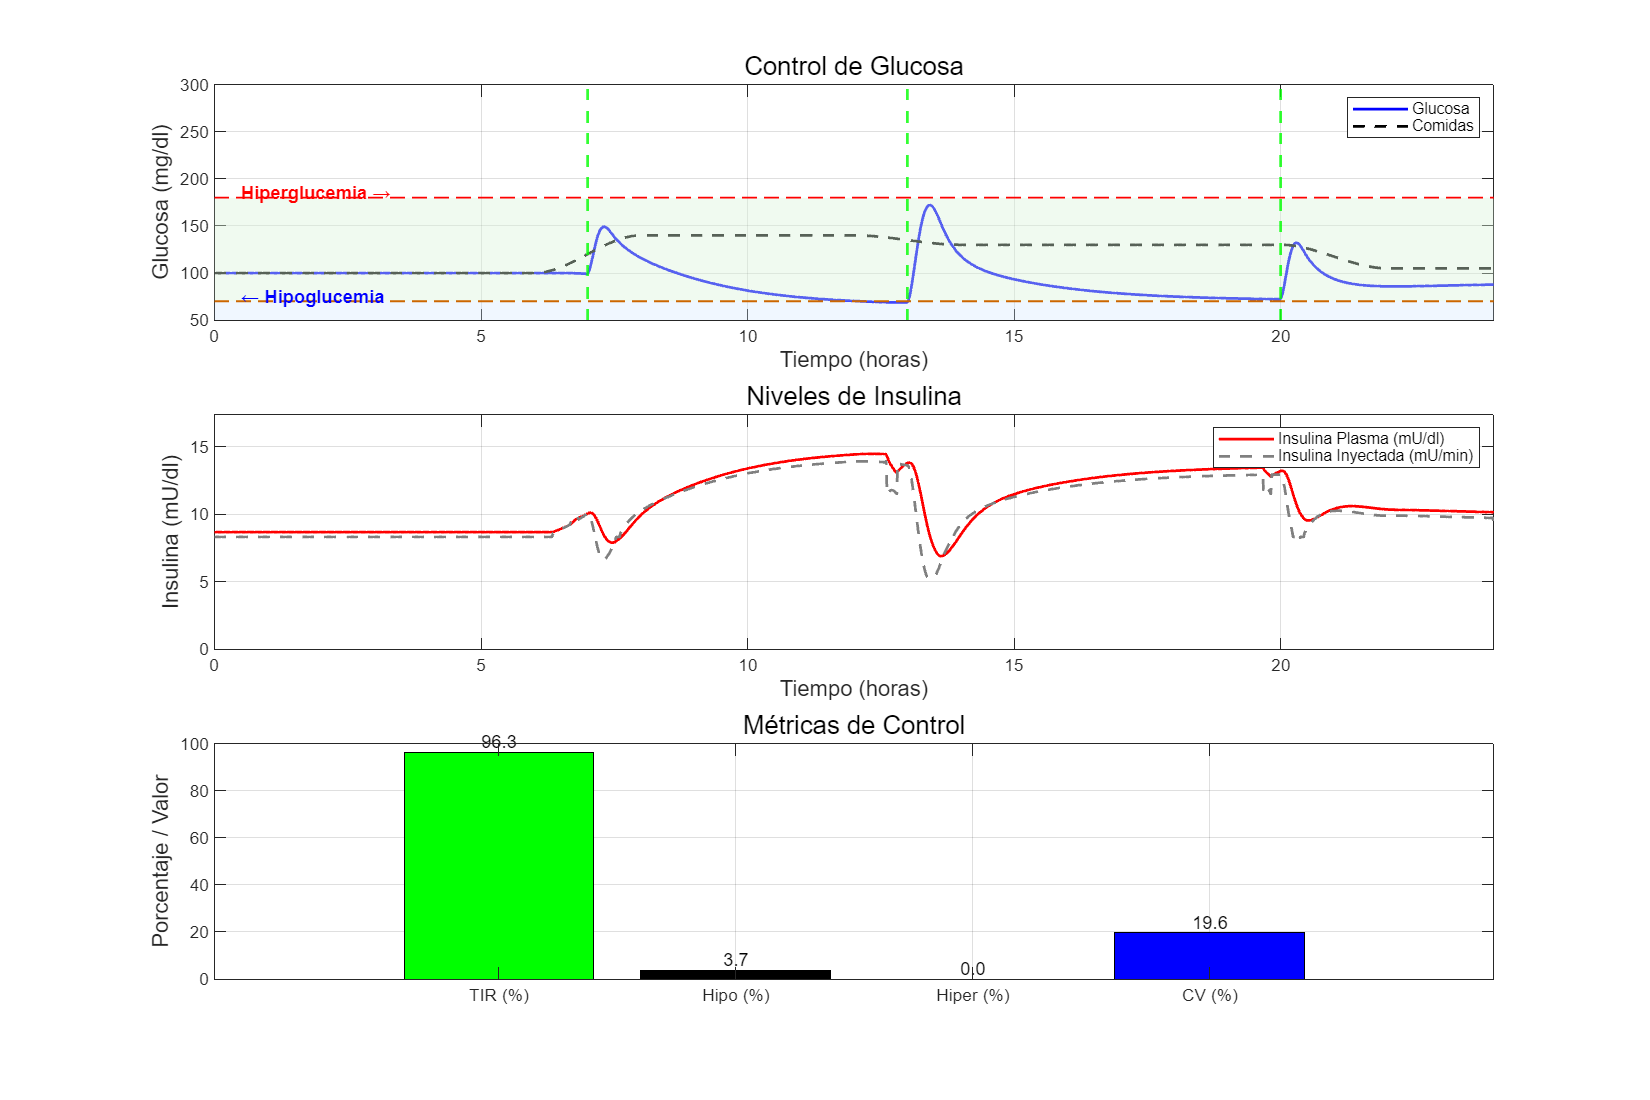

figure('Color','w', 'Position', [100 100 1200 800]);

subplot(3,1,1); 
plot(tspan/60, G, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Glucosa'); 
hold on;
plot(tspan/60, G_ref_vals, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Referencia Dinámica'); % Plot the dynamic reference

fill([0 24 24 0], [0 0 70 70], [0.8 0.9 1], 'EdgeColor', 'none', 'FaceAlpha', 0.3); 

fill([0 24 24 0], [70 70 180 180], [0.85 0.95 0.85], 'EdgeColor', 'none', 'FaceAlpha', 0.4); 

plot([0 24], [70 70], '--r', 'Color', [0.8 0.4 0], 'LineWidth', 1); 
plot([0 24], [180 180], '--r', 'LineWidth', 1); 
text(0.5, 75, '← Hipoglucemia', 'Color', 'blue', 'FontWeight','bold');
text(0.5, 185, 'Hiperglucemia →', 'Color', 'red', 'FontWeight','bold', 'HorizontalAlignment','left');

for j = 1:length(meal_times)
    xline(meal_times(j)/60, '--g', 'LineWidth', 1.5, 'Alpha', 0.8);
end

title('Control de Glucosa', 'FontSize', 14, 'FontWeight', 'normal');
ylabel('Glucosa (mg/dl)', 'FontSize', 12);
xlabel('Tiempo (horas)', 'FontSize', 12);
xlim([0 24]);
ylim([50 300]); 
grid on; 

h_glucose = plot(NaN, NaN, 'b-', 'LineWidth', 1.5); 
h_ref = plot(NaN, NaN, 'k--', 'LineWidth', 1.5);
h_meals = plot(NaN, NaN, '--r', 'LineWidth', 1.5); 
legend([h_glucose, h_ref], 'Glucosa', 'Comidas', 'Location', 'northeast');

% Niveles de Insulina 
subplot(3,1,2);
plot(tspan/60, I_plasma, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Insulina Plasma (mU/dl)'); 
hold on;
plot(tspan/60, U_total, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5, 'DisplayName', 'Insulina Inyectada (mU/min)'); 

title('Niveles de Insulina', 'FontSize', 14, 'FontWeight', 'normal');
ylabel('Insulina (mU/dl)', 'FontSize', 12); 
xlabel('Tiempo (horas)', 'FontSize', 12);
xlim([0 24]);
ylim([0 max([max(I_plasma), max(U_total)])*1.2]); 
grid on;
legend('Location', 'northeast');

% Métricas de Control 
subplot(3,1,3);
bar_labels = {'TIR (%)', 'Hipo (%)', 'Hiper (%)', 'CV (%)'};
bar_data = [time_in_range_standard, time_below_70, time_above_180, CV]; 

b = bar(bar_data, 'FaceColor', 'flat');
b.CData(1,:) = [0 1 0]; 
b.CData(2,:) = [0 0 0]; 
b.CData(3,:) = [0 0 0]; 
b.CData(4,:) = [0 0 1]; 
set(gca, 'xticklabel', bar_labels);

ylabel('Porcentaje / Valor', 'FontSize', 12);
title('Métricas de Control', 'FontSize', 14, 'FontWeight', 'normal');
ylim([0 100]); 
grid on;

for k = 1:length(bar_data)
    text(k, bar_data(k), num2str(bar_data(k), '%.1f'), ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom', ...
        'FontSize', 10);
end

function ref_val = smooth_glucose_reference(t_min)
    t_hour = mod(t_min / 60, 24); 
    if t_hour >= 0 && t_hour < 6
        ref_val = 100;
    elseif t_hour >= 6 && t_hour < 8
        alpha = (t_hour - 6) / 2; % 0 a 1 en 2 horas
        ref_val = 100 + (140 - 100) * (3*alpha^2 - 2*alpha^3); % 
    elseif t_hour >= 8 && t_hour < 12
        ref_val = 140;
    elseif t_hour >= 12 && t_hour < 14 % Transición gradual
        alpha = (t_hour - 12) / 2;


=== ÍNDICES DE DESEMPEÑO CONTROL PID ===


        ref_val = 140 + (130 - 140) * (3*alpha^2 - 2*alpha^3);

IAE: 41549.99


    elseif t_hour >= 14 && t_hour < 20

ISE: 2064531.02


        ref_val = 130;

ITAE: 36645389.12


    elseif t_hour >= 20 && t_hour < 22 % Transición gradual
        alpha = (t_hour - 20) / 2;
        ref_val = 130 + (105 - 130) * (3*alpha^2 - 2*alpha^3);
    else % 22 a 24
        ref_val = 105;
    end
end

function profile = smooth_meal_profile(t, meal_start, duration)
    if t >= meal_start && t <= meal_start + duration
        x = (t - meal_start) / duration;
        profile = 4 * x * (1 - x)^3; 
    else
        profile = 0;
    end
end

function profile = smooth_bolus_profile(t, bolus_start, duration)
    if t >= bolus_start && t <= bolus_start + duration
        x = (t - bolus_start) / duration;
        profile = sin(pi * x) / duration; 
    else
        profile = 0;
    end
end

function dydt = modelo_no_lineal(t, y, p1, p2, p3, p4, Gb, Ib, VI, U, D_func_handle)
    G = y(1); X = y(2); I_plasma = y(3); Dt = y(4); Gsc = y(5);
    D_val = D_func_handle(t);
    dGdt = -(p1 + X)*G + p1*Gb + Dt;
    dXdt = -p2*X + p3*(I_plasma - Ib);
    dIdt = -p4*I_plasma + U/VI;
    dDdt = -2*Dt + 2*D_val; 
    dGscdt = (1/5)*(G - Gsc); 
    dydt = [dGdt; dXdt; dIdt; dDdt; dGscdt];
end

abs_error = abs(Error);
squared_error = Error.^2;
time_weighted_abs_error = tspan .* abs_error;

% Cálculo de índices
IAE = trapz(tspan, abs_error);             % Integral del valor absoluto del error
ISE = trapz(tspan, squared_error);         % Integral del error al cuadrado
ITAE = trapz(tspan, time_weighted_abs_error); % Integral del error absoluto ponderado por el tiempo

% Mostrar resultados
fprintf('\n=== ÍNDICES DE DESEMPEÑO CONTROL PID ===\n');
fprintf('IAE: %.2f\n', IAE);
fprintf('ISE: %.2f\n', ISE);
fprintf('ITAE: %.2f\n', ITAE);

#### Conclusiones:

La gráfica muestra que el controlador PID, combinado con bolos anticipados y una referencia de glucosa dinámica, logra mantener los niveles de glucosa en sangre dentro del rango clínicamente deseado durante casi todo el día. La glucosa posprandial se eleva  tras cada comida, pero rápidamente vuelve a valores seguros sin provocar hipoglucemias graves ni rebotes significativos. El tiempo en rango (96.3 %) y el bajo coeficiente de variación (19.6 %) reflejan un control glucémico efectivo y estable.